load EPLresults.mat

homegf = EPL.HomeGF

homegf =     35
    31
    35
    47
    27
    39
    34
    33
    22
    32

awaygf = EPL.AwayGF

awaygf =     33
    34
    34
    24
    22
    20
    31
    30
    19
    27


bighomewinner = EPL.HomeWins >= 10

bighomewinner =    1
   1
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0

betterathome = homegf >= awaygf

betterathome =    1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   0
   1
   1
   1


both = bighomewinner & betterathome %and

both =    1
   0
   1
   1
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0

either = bighomewinner | betterathome %or

either =    1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   0
   1
   1
   1

betteraway = ~betterathome %not

betteraway =    0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   1
   0
   1
   0
   0
   0

EPL.Team(1:10) %numeric indexing

ans =     'Leicester City'
    'Arsenal'
    'Tottenham Hotspur'
    'Manchester City'
    'Manchester United'
    'Southampton'
    'West Ham United'
    'Liverpool'
    'Stoke City'
    'Chelsea'


EPL.Team(both) %logical indexing

ans =     'Leicester City'
    'Tottenham Hotspur'
    'Manchester City'
    'Manchester United'
    'Southampton'


EPL(both,:)

ans =            Team            HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points    GD
    ___________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______    ______    __
    'Leicester City'       12          6            1             35        18        11          6            2             33        18        81        32
    'Tottenham Hotspur'    10          6            3             35        15


sum(both)

ans = 5

nnz(both)

ans = 5


r = find(both)

r =      1
     3
     4
     5
     6

evenly = homegf == awaygf

evenly =    0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0

nnz(evenly)

ans = 1

EPL(evenly,:)

ans =       Team       HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points    GD 
    _________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______    ______    ___
    'Watford'    6           6            7             20        19        6           3            10            20        31        45        -10


notevenly = homegf ~= awaygf

notevenly =    1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1

%EPL.Team == 'Arsenal'

strcmpi(EPL.Team,'Arsenal')

ans =    0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0

homewinning = EPL.HomeWins >= EPL.HomeLosses

homewinning =    1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   0
   0
   0
   0
   0
   1
   0
   0

awaywinning = EPL.AwayWins >= EPL.AwayLosses

awaywinning =    1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0

winning = homewinning & awaywinning

winning =    1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


EPL(winning,:)

ans =            Team            HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points    GD
    ___________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______    ______    __
    'Leicester City'       12          6            1             35        18        11          6            2             33        18        81        32
    'Arsenal'              12          4            3             31        11


morehomegoals = homegf >= awaygf

morehomegoals =    1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   0
   1
   1
   1


HFA = homewinning | morehomegoals

HFA =    1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   0
   1
   1
   1


EPL(HFA,:)

ans =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points    GD 
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______    ______    ___
    'Leicester City'          12          6             1            35        18        11          6             2            33        18        81         32
    'Arsenal'                 12          4             3         


bigHFA = (homegf >= 30) & (homegf >= 2*awaygf);

EPL(bigHFA,:)

ans =            Team           HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points    GD 
    __________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______    ______    ___
    'Newcastle United'    7           7            5             32        24        2           3            14            12        41        37        -21

nnz(bigHFA)

ans = 1

combined = [winning, bigHFA, morehomegoals]

combined =    1   0   1
   1   0   0
   1   0   1
   1   0   1
   0   0   1
   1   0   1
   1   0   1
   1   0   1
   0   0   1
   1   0   1
   0   0   1
   0   0   0
   0   0   1
   0   0   1
   0   0   0
   0   0   1
   0   0   0
   0   1   1
   0   0   1
   0   0   1


sum(combined)

ans =      8     1    16

nnz(combined)

ans = 25


idx = find(combined)

idx =      1
     2
     3
     4
     6
     7
     8
    10
    38
    41

[r,c] = find(combined)

r =      1
     2
     3
     4
     6
     7
     8
    10
    18
     1

c =      1
     1
     1
     1
     1
     1
     1
     1
     2
     3

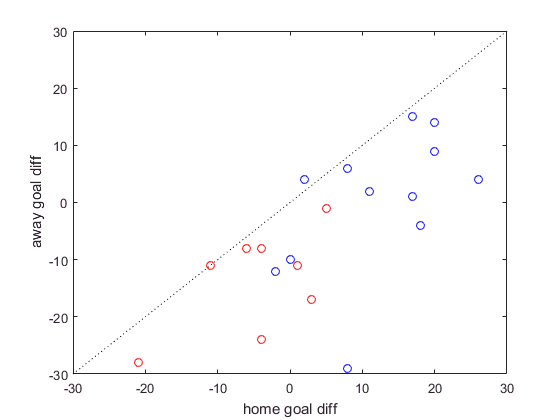

% measure of perfomance
HGD = EPL.HomeGF - EPL.HomeGA;
AGD = EPL.AwayGF - EPL.AwayGA;
% plot(HGD,AGD,'o')
plot(HGD(homewinning),AGD(homewinning),'bo')
hold on
plot(HGD(~homewinning),AGD(~homewinning),'ro')
xlabel('home goal diff')
ylabel('away goal diff')
%hold on
plot([-30 30],[-30 30],'k:')
hold off

legend('homewinners','non-homewinners',...
    'location','NW')


